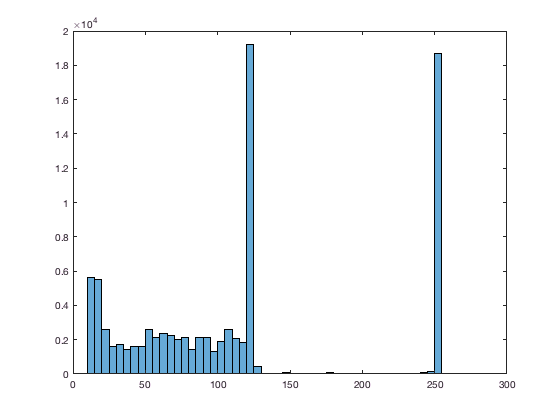

clc
clear all
close all

Im = imread('globe.png');
Im_size(:)=size(Im);%Gather size data of image
X=Im_size(1);%Save the x dimension
Y=Im_size(2);%Save the Y dimension

histogram(Im)


%Add or remove thresholds in the line below according to the histogram
thresh = [0,117,200]

thresh =      0   117   200


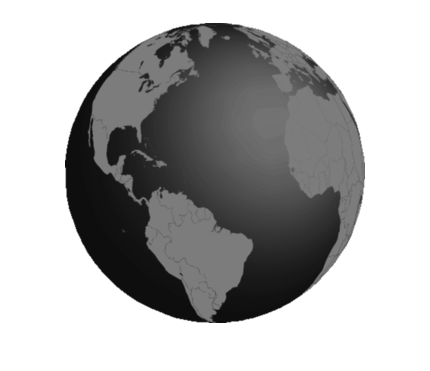


%Convert the image based on the thresholds
Im_Shaded = imquantize(Im,thresh);

%fileID = fopen('Untitled.txt','wt');
%fprintf(fileID,'%f',Im_Shaded);
%fclose(fileID);

imshow(Im);

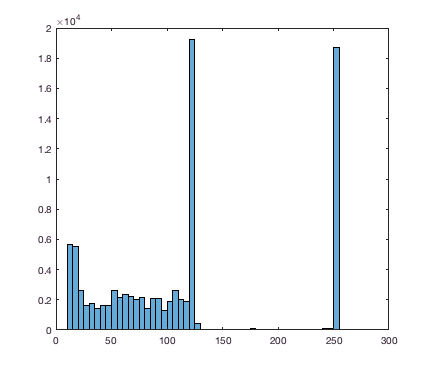

histogram(Im)

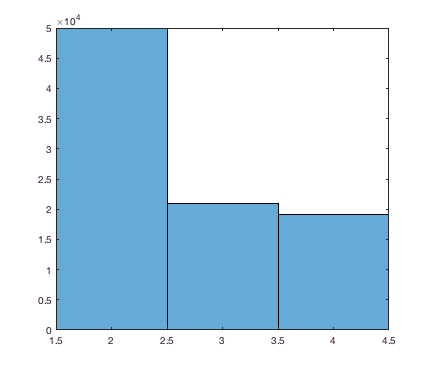

histogram(Im_Shaded)

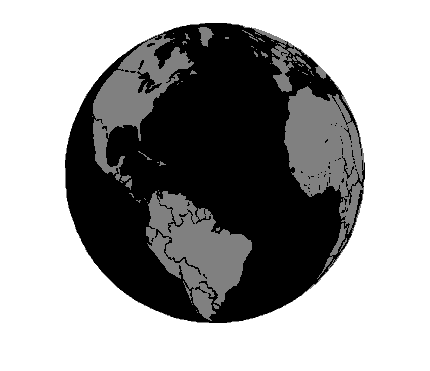

imshow(Im_Shaded,[]);


%Now isolating each shade as a seperate b and w image
max_value=max(Im_Shaded(:))

max_value = 4

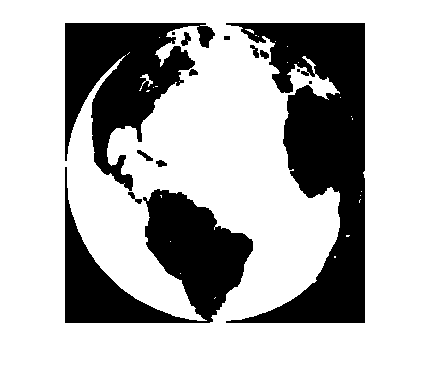


for i = 1:(max_value-1)
    Im_array(:,:,i)=im2bw(Im,thresh(i)/255);
    
end

for i = 1:(max_value-2)
    Im_array_seperate(:,:,i)=Im_array(:,:,i)-bwmorph(Im_array(:,:,i+1),'dilate');
    Im_array_seperate(:,:,i)=imclearborder(Im_array(:,:,i));
    Im_array_seperate(:,:,i)=(Im_array(:,:,i)-bwmorph(Im_array(:,:,i+1),'dilate'));
    Im_array_seperate(:,:,i+1)=(~Im_array(:,:,i+1));
end

%-------------------------------------------
Im_array_seperate(:,:,2) = imclearborder(Im_array_seperate(:,:,2));
imshow(Im_array_seperate(:,:,1));

num_objects_1 = max(max(bwlabel(Im_array_seperate(:,:,1))))

num_objects_1 = 28

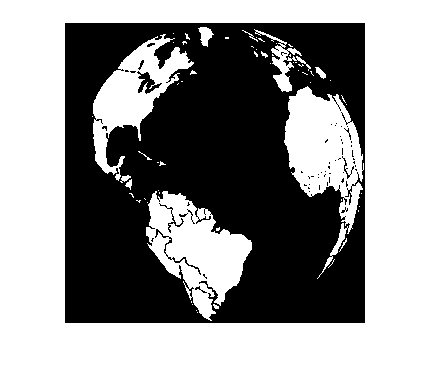

imshow(Im_array_seperate(:,:,2));

num_objects_2 = max(max(bwlabel(Im_array_seperate(:,:,2))))

num_objects_2 = 60

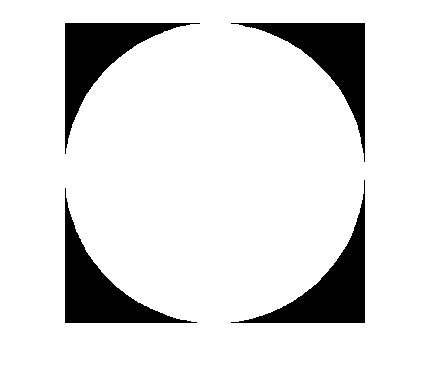

imshow(Im_array_seperate(:,:,3));

num_objects_3 = max(max(bwlabel(Im_array_seperate(:,:,3))))

num_objects_3 = 1

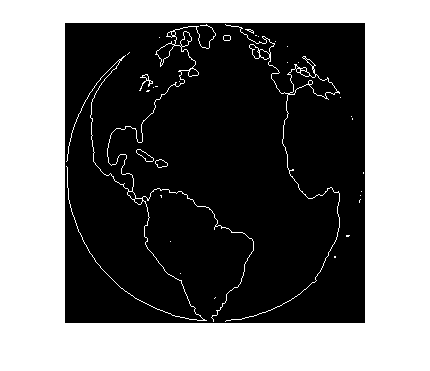



%Converts the different shades into outlines
Im_array_outline(:,:,1) = (bwmorph(Im_array_seperate(:,:,1),'remove')-(bwmorph(Im_array_seperate(:,:,3),'remove')));
%imshow(Im_array_seperate(:,:,2));
Im_array_outline(:,:,2) = (bwmorph(bwmorph(Im_array_seperate(:,:,2),'remove'),'clean')-(bwmorph(Im_array_seperate(:,:,3),'remove')));
Im_array_outline(:,:,3) = bwmorph(Im_array_seperate(:,:,3),'remove');
imshow(Im_array_outline(:,:,1));

num_objects_1 = max(max(bwlabel(Im_array_outline(:,:,1))))

num_objects_1 = 27

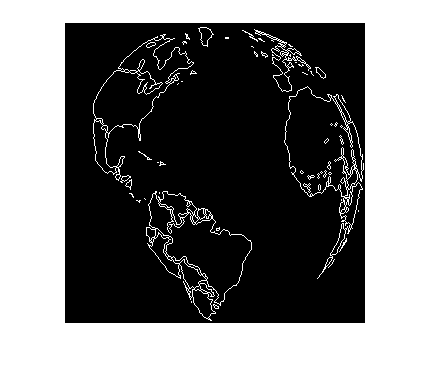

imshow(Im_array_outline(:,:,2));

num_objects_2 = max(max(bwlabel(Im_array_outline(:,:,2))))

num_objects_2 = 48

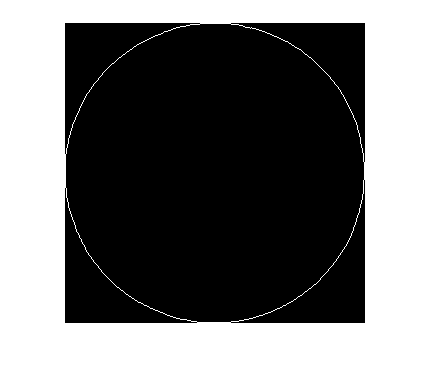

imshow(Im_array_outline(:,:,3));

num_objects_3 = max(max(bwlabel(Im_array_outline(:,:,3))))

num_objects_3 = 1

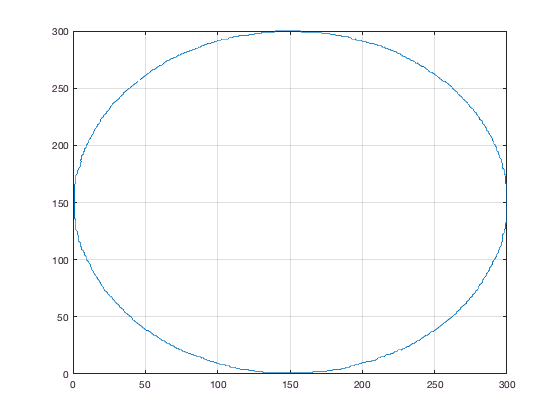



[ x_fin, y_fin, x_move, y_move, final_x_1, final_y_1, num_steps ] = conv_to_moves( Im_array_outline(:,:,3), 1, Y);

fileID = fopen('image_data.h','w');
fprintf(fileID,'int num_of_steps = ');
fprintf(fileID,'%1i;\n\n',num_steps);
fprintf(fileID,'// list of coordinates\n');
fprintf(fileID,'int coordinates[');
fprintf(fileID,'%1i',num_steps*4);
fprintf(fileID,'] = {');
for i = 1:num_steps
    fprintf(fileID,' %1i, %2i',x_fin(i),300-y_fin(i));
    if (num_steps ~= i)
        fprintf(fileID,',');
    end
end
fprintf(fileID,'};\n\n');
fprintf(fileID,'//Move list from origin point (0,0) \n');
fprintf(fileID,'//Every four numbers is (XL, XR, YD, YU) \n');
fprintf(fileID,'int move_list[');
fprintf(fileID,'%1i',num_steps*4);
fprintf(fileID,'] = {');

for i = 1:num_steps
    if x_move(i) < 0
    fprintf(fileID,' %1i, 0',0-x_move(i));
    else
    fprintf(fileID,' 0, %1i',x_move(i));
    end
        fprintf(fileID,',');
    if y_move(i) < 0
    fprintf(fileID,' %1i, 0',0-y_move(i));
    else
    fprintf(fileID,' 0, %1i',y_move(i));
    end
    if (num_steps ~= i)

        fprintf(fileID,',');
    end
end

fprintf(fileID,'};\n//Fin');

figure
plot(x_fin,y_fin)
grid on


fclose(fileID);

type image_data.h


int num_of_steps = 847;

// list of coordinates
int coordinates[3388] = { 45, 44, 44, 45, 43, 46, 42, 47, 41, 48, 40, 49, 39, 50, 38, 51, 37, 52, 36, 53, 35, 54, 35, 55, 34, 56, 33, 57, 32, 58, 32, 59, 31, 60, 30, 61, 29, 62, 28, 63, 27, 64, 27, 65, 26, 66, 26, 67, 25, 68, 25, 69, 24, 70, 23, 71, 23, 72, 22, 73, 21, 74, 21, 75, 20, 76, 19, 77, 19, 78, 19, 79, 18, 80, 18, 81, 17, 82, 17, 83, 16, 84, 16, 85, 15, 86, 15, 87, 14, 88, 14, 89, 14, 90, 13, 91, 13, 92, 12, 93, 12, 94, 11, 95, 11, 96, 11, 97, 10, 98, 10, 99, 9, 100, 9, 101, 9, 102, 8, 103, 8, 104, 8, 105, 7, 106, 7, 107, 7, 108, 6, 109, 6, 110, 6, 111, 6, 112, 5, 113, 6, 114, 5, 115, 5, 116, 5, 117, 5, 118, 5, 119, 4, 120, 4, 121, 3, 122, 3, 123, 3, 124, 3, 125, 2, 126, 2, 127, 2, 128, 2, 129, 2, 130, 2, 131, 2, 132, 2, 133, 1, 134, 1, 135, 1, 136, 1, 137, 1, 138, 1, 139, 1, 140, 1, 141, 1, 142, 1, 143, 1, 144, 1, 145, 1, 146, 1, 147, 1, 148, 1, 149, 1, 150, 1, 151, 1, 152, 1, 153, 1, 154, 1, 155, 1, 156, 1, 157, 1, 158, 1, 15